% AAE 532 HW 5 Problem 3
% Tomoki Koike
close all; clear all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Fall\AAE532\matlab\outputs\ps5';
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
format shortG;

% Set constants
planet_consts = setup_planetary_constants();  % Function that sets up all the constants in the table 
earth = planet_consts.earth;  % structure of earth
G = 6.6743015e-20;  % Gravitational constant [km^3/kg/s^2]

% Setup
Re = earth.mer;
rvec_i = Re*[0.15, -1.44, -0.65];  % the position vector in inertial frame
vvec_i = [6.62, 2.7, -1.56];  % the velocity vector in inertial frame 
mu = earth.gp;  % gravitational parameter  

r = norm(rvec_i)  % magnitude of the position vector 

r =         10122


v = norm(vvec_i)  % magnitude of the velocity vector 

v =        7.3176


hvec_i = cross(rvec_i, vvec_i)  % the h vector perpendicular to the position and velocity vectors

hvec_i =         25521       -25953        63385


hhat_i = hvec_i / norm(hvec_i)  % the unit h vector in inertial frame

hhat_i =       0.34917     -0.35507      0.86719


h = norm(hvec_i)  % magnitude of the h vector

h =         73092


rhat_i = rvec_i / r  % the unit r vector in inertial frame

rhat_i =      0.094517     -0.90737     -0.40958


thetahat_i = cross(hhat_i, rhat_i)  % the unit vector of theta direction

thetahat_i =       0.93228      0.22497     -0.28326


check = v < sqrt(2 * mu / r)  % check to see if this orbit is an ellipse

check = logical
   1


a = (-mu / 2) / (v^2/2 - mu/r)  % semi major axis

a =         15811


e = sqrt(1 - h^2 / mu / a)  % the eccentricity

e =       0.39026


rp = a*(1 - e)  % radius of periapsisc

rp =        9640.7


ra = a*(1 + e)  % radius of apoapsis

ra =         21982


p = a*(1 - e^2) % semi latus rectum

p =         13403



% Check that there are no collisions with the Earth
check = rp > Re

check = logical
   1


check = ra > Re

check = logical
   1


thetastar = acos_dbval(1/e * (p/r - 1), "deg")  % double valued true anomaly

thetastar =        33.843      -33.843



i = acos_dbval(hhat_i(3), "deg")

i =        29.867      -29.867


i = i(0 <= i & i <= 180)  % inclination

i =        29.867


 
Omega1 = asin_dbval(hhat_i(1) / sind(i), "deg")

Omega1 =         44.52       135.48


Omega2 = -acos_dbval(hhat_i(2) / sind(i), "deg")

Omega2 =       -135.48       135.48


Omega = intersect(round(Omega1,5), round(Omega2,5))

Omega =        135.48



theta1 = asin_dbval(rhat_i(3) / sind(i), "deg")

theta1 =       -55.332      -124.67


theta2 = acos_dbval(thetahat_i(3) / sind(i), "deg")

theta2 =        124.67      -124.67


theta = intersect(round(theta1,5), round(theta2,5))

theta =       -124.67


rdot = dot(vvec_i, rhat_i)

rdot =       -1.1852


thetastar = thetastar(thetastar < 0)

thetastar =       -33.843


omega = theta - thetastar

omega =       -90.825


gamma = -acosd(h /r / v)

gamma =       -9.3213


E = T2E_anomaly(e, thetastar, "deg")

E =       -22.783


M = rad2deg(deg2rad(E) - e*sind(E))

M =       -14.124


dtp = deg2rad(M+360)*sqrt(a^3 / mu)

dtp =         19010


dtp_day = dtp / 60 / 60/ 24

dtp_day =       0.22002


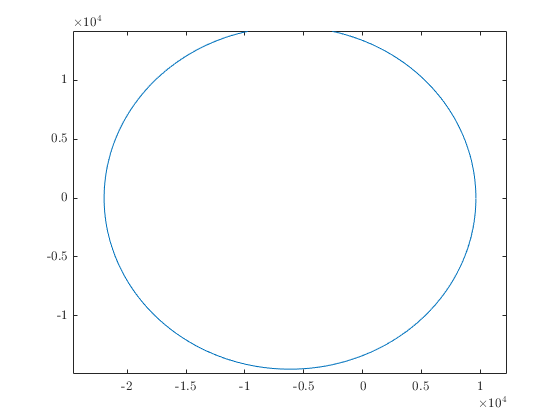

ang = [0:0.01:2*pi];
R = p./(1 + e*cos(ang));
X = R .* cos(ang);
Y = R .* sin(ang);
plot(X,Y)
axis equal

function res = asin_dbval(x, unit)
    if unit == "deg"
        ang1 = asind(x);
        if (0<=ang1 && ang1<=180)
            ang2 = 180 - ang1;
        elseif -90<=ang1 && ang1<0
            ang2 = -ang1 - 180;
        else
            ang2 = 540 - ang1;
        end
    else 
        ang1 = asin(x);
        if (0<=ang1 && ang1<=pi)
            ang2 = pi - ang1;
        elseif -pi/2<=ang1 && ang1<0
            ang2 = -ang1 - pi;
        else
            ang2 = 3*pi - ang1;
        end
    end
    res = [ang1, ang2];
end

function res = acos_dbval(x, unit)
    if unit == "deg"
        ang1 = acosd(x);
        if (0<=ang1 && ang1<=180)
            ang2 = -ang1;
        else
            ang2 = 360 - ang1;
        end
    else 
        ang1 = asin(x);
        if (0<=ang1 && ang1<pi) 
            ang2 = -ang1;
        else
            ang2 = 2*pi - ang1;
        end
    end
    res = [ang1, ang2];
end
    